# Center Formal Image in a PDF Report

This example shows how to center a formal image, which is an image with a caption, on a landscape page for PDF reports.

The example creates a Report API PDF report that has landscape layout and uses the `centerFormalImage` local function to add the formal images at the center of the page.

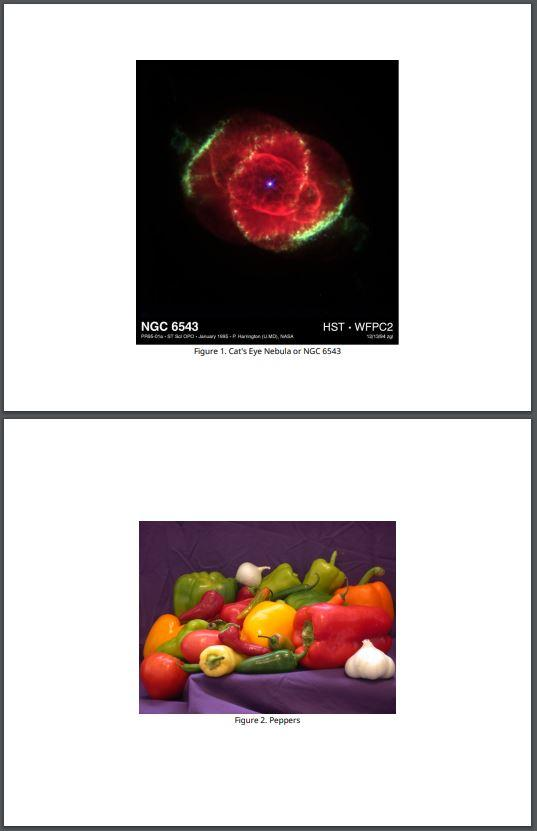

## Create Report

Import the DOM and Report API packages so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*
import mlreportgen.report.*

Create a PDF report.

rpt = Report("myreport","pdf");
open(rpt);

## Update the Report Page Layout

Create a page layout object.

pageLayoutObj = PDFPageLayout;

Specify the page orientation, height, and width.

pageLayoutObj.PageSize.Orientation = "landscape";
pageLayoutObj.PageSize.Height = "8.5in";
pageLayoutObj.PageSize.Width = "11in";

Specify the page margins.

pageLayoutObj.PageMargins.Top = "0.5in";
pageLayoutObj.PageMargins.Bottom = "0.5in";
pageLayoutObj.PageMargins.Left = "0.5in";
pageLayoutObj.PageMargins.Right = "0.5in";

pageLayoutObj.PageMargins.Header = "0.3in";
pageLayoutObj.PageMargins.Footer = "0.3in";

Add the page layout object to the report.

add(rpt,pageLayoutObj);

## Create and Add Formal Images

Create formal images and call the `centerFormalImage` local function to add these formal images at the center of the page.

formalImg1 = FormalImage( ...
    "Image",which("ngc6543a.jpg"), ...
    "Caption","Cat's Eye Nebula or NGC 6543");
centerFormalImage(formalImg1,rpt);

formalImg2 = FormalImage( ...
    "Image",which("peppers.png"), ...
    "Caption","Peppers");
centerFormalImage(formalImg2,rpt);

## Generate the Report

Close and view the report.

close(rpt);
rptview(rpt);

## The `centerFormalImage` Local Function

This function adds the specified formal image at the center of the page in the specified PDF report. The function uses an invisible DOM `Table` to do the layout.

function centerFormalImage(formalImage,rpt)

Import the DOM API, Report API, and report generator utility packages so that you do not have to use long, fully qualified class names.

    import mlreportgen.dom.*
    import mlreportgen.report.*
    import mlreportgen.utils.*

To determine the current page size and the page margin, get the current page layout of the report. The page layout information is used to size the table that is created in a subsequent step.

    pageLayout = getReportLayout(rpt);
    pageSize = pageLayout.PageSize;
    pageMargins = pageLayout.PageMargins;

Calculate the page body width. The page body width denotes the page width that is available for the content. For a PDF report, the page body width is determined by subtracting the left and right margin size from the page width.

    bodyWidth = units.toInches(pageSize.Width) - ...
        units.toInches(pageMargins.Left) - ...
        units.toInches(pageMargins.Right);
    bodyWidth = sprintf("%0.2fin",bodyWidth);

Calculate the page body height. The page body height denotes the page height that is available for the content. For a PDF report, the page body height is determined by subtracting the top margin, bottom margin, header, and footer size from the page height.

    bodyHeight = units.toInches(pageSize.Height) - ...
        units.toInches(pageMargins.Top) - ...
        units.toInches(pageMargins.Bottom) - ...
        units.toInches(pageMargins.Header) - ...
        units.toInches(pageMargins.Footer);
    bodyHeight = sprintf("%0.2fin",bodyHeight);

Use the `getImageReporter` method of the `FormalImage` reporter to get the image reporter and the `getCaptionReporter` method to get the caption reporter.

    imageReporter = getImageReporter(formalImage,rpt);
    captionReporter = getCaptionReporter(formalImage);

Use the `getImpl` methods of the image and caption reporters to get the corresponding DOM implementations.

    imageImpl = getImpl(imageReporter,rpt);
    captionImpl = getImpl(captionReporter,rpt);

The DOM implementations contain a DOM `Paragraph` that contains the image and caption content. Update the style of the paragraphs to make sure that there is no white space around the paragraphs and that they are centered in the table entry that is created in a subsequent step.

    paraStyle = { ...
        OuterMargin("0in","0in","0in","0in"), ...
        HAlign("center") ...
        };
    
    imagePara = clone(imageImpl.Children(1));
    imagePara.Style = [imagePara.Style, paraStyle];
    
    captionPara = clone(captionImpl.Children(1));
    captionPara.Style = [captionPara.Style, paraStyle];

Create a 1-by-1 invisible layout table (`lo_table`). A table is considered invisible when the borders are not defined for the table and its table entries.

    lo_table = Table(1);
    row = append(lo_table,TableRow);
    entry = append(row,TableEntry);

Add the paragraphs that contain the image and caption content to the only table entry in the invisible layout table.

    append(entry,imagePara);
    append(entry,captionPara);

Span the table to the available page body width.

    lo_table.Width = bodyWidth;

Span the only table entry to the available page body height. Specify the vertical and horizontal alignment formats to make sure that the image and caption are centered both vertically and horizontally inside the table entry.

    lo_table.TableEntriesStyle = [lo_table.TableEntriesStyle ...
        { ...
        Height(bodyHeight), ...
        HAlign("center"), ...
        VAlign("middle") ...
        }];

Add the layout table to the report.

    add(rpt,lo_table);
end

*Copyright 2020 The MathWorks, Inc.*